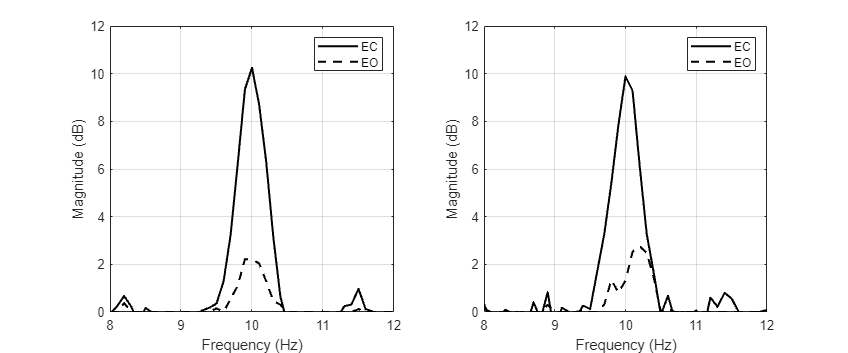

% Frequency vector from 8 to 12 Hz
freq = 8:0.1:12;

% EC peak at 10 Hz with peak amplitude around 10 dB
EC_peak_amp = 10;
EC_peak_freq = 10;
EC_aligned = EC_peak_amp * exp(-((freq - EC_peak_freq).^2) / (2 * 0.2^2));
% Add noise to EC
EC_noise_level = 0.4;
EC_aligned = EC_aligned + EC_noise_level * randn(size(freq));

% EO peak amplitude reduced, peak around 5 dB
EO_peak_amp = 2;
EO_peak_freq = EC_peak_freq; % Aligned peaks
EO_aligned = EO_peak_amp * exp(-((freq - EO_peak_freq).^2) / (2 * 0.2^2));
% Add noise to EO
EO_noise_level = 0.5;
EO_aligned = EO_aligned + EO_noise_level * randn(size(freq));
% Ensure EO is below EC
EO_aligned = min(EO_aligned, EC_aligned - 0.2);
% Prevent negative values
EO_aligned(EO_aligned < 0) = 0;

% Misaligned peaks: EC at 10 Hz, EO shifted more to the left (e.g., 9.5 Hz)
EC_misaligned = EC_peak_amp * exp(-((freq - EC_peak_freq).^2) / (2 * 0.2^2));
% Add noise to EC
EC_misaligned = EC_misaligned + EC_noise_level * randn(size(freq));

EO_misaligned_peak_amp = 3; % EO peak below EC
EO_misaligned_peak_freq = 10.2; % Shifted more to the left
EO_misaligned = EO_misaligned_peak_amp * exp(-((freq - EO_misaligned_peak_freq).^2) / (2 * 0.2^2));
% Add noise to EO
EO_misaligned = EO_misaligned + EO_noise_level * randn(size(freq));
% Ensure EO is below EC
EO_misaligned = min(EO_misaligned, EC_misaligned - 0.2);
% Prevent negative values
EO_misaligned(EO_misaligned < 0) = 0;

% Create figure with two subplots
figure('Position', [100, 100, 1200, 500]);

% Plot for aligned peaks
subplot(1,2,1);
plot(freq, EC_aligned, 'k-', 'LineWidth', 1.5); % EC with black solid line
hold on;
plot(freq, EO_aligned, 'k--', 'LineWidth', 1.5); % EO with black dotted line
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title(''); %Aligned Peaks
legend('EC', 'EO');
grid on;
ylim([0, 12]);

% Plot for misaligned peaks
subplot(1,2,2);
plot(freq, EC_misaligned, 'k-', 'LineWidth', 1.5); % EC with black solid line
hold on;
plot(freq, EO_misaligned, 'k--', 'LineWidth', 1.5); % EO with black dotted line
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title(''); %Misaligned Peaks
legend('EC', 'EO');
grid on;
ylim([0, 12]);